# Q3. Steady state conduction in infinitely long, and insulated fin of cylindrical cross section.

## By- Anish Dhar, 211020067

- FOR Insulated Tip

L = 1;
dx = 0;
% Sc and St are the coefficients from Q = Sc + St * T
N_points = 100;
K = 0.5;
Q_gen = 0; % W/m^3
area = 1;
St = -1;
Sc = 1000;
Ti = 100;
Perimeter = 1;
H = 0;
T_amb = 20;
m = 5;

ANALYTICAL SOLUTION FOR INSULATED TIP:

array_temps_analytical = zeros(N_points+2, 2);
dx = zeros(N_points + 2, 1);
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);
x(1) = 0;
for i = 2:1:N_points+2 % Getting all the points from the delta
x(i) = x(i-1) + dx(i-1);
end
for i = N_points+2:-1:1
array_temps_analytical(i,1) = T_amb + (Ti - T_amb)*cosh(m*(L-x(i)))/cosh(m*L);
array_temps_analytical(i,2) = x(i);
% disp(array_temps(i))
end

% disp(Z);

NUMERICAL SOLUTION FOR INSULATED TIP:

% Initializing important parameters for the given problem
x = zeros(N_points+2, 1); % For the unit lengths
a = zeros(N_points+2, 1); % For the right side of the matrix diagonal elements
b = zeros(N_points+2, 1); % For the left side of the matrix diagonal elements
d = zeros(N_points+2, 1); % For the diagonal Elements of the matrix
c = zeros(N_points+2, 1); % For the equation's answers

array_temps = zeros(N_points+2, 2); % For the equation's answers

dx = zeros(N_points + 2, 1);
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);
% disp(dx)

x(1) = 0;
for i = 2:1:N_points+2 % Getting all the points from the delta
x(i) = x(i-1) + dx(i-1);
end

% Initial Boundary Conditions
a(1) = 0;
b(1) = 0;
c(1) = Ti;
d(1) = 1;
m2 = 25;

% Thermal Conductivity for the remaining points except for the last one
for i = 2:1:N_points+1
    d(i) = -(1/(dx(i-1)) + 1/dx(i+1) + m2*(L/N_points)); % ST
    a(i) = (1/dx(i+1));
    b(i) = (1/dx(i-1));
    c(i) = (-m2*T_amb)*(L/N_points); % SC
end

% Final Boundary Conditions
a(N_points + 2) = 0;
b(N_points + 2) =-1;
d(N_points + 2) = -b(N_points+2);
c(N_points + 2) = 0;

for i = 2:1:N_points+2
    d(i) = d(i) - b(i)*a(i-1)/d(i-1);
    c(i) = c(i) - b(i)*c(i-1)/d(i-1);
end

for i = 1:1:N_points+2
    disp(d(i));
end

     1

 -300.2500

 -166.9444

 -140.3498

 -128.9995

 -122.7303

 -118.7705

 -116.0540

 -114.0832

 -112.5947

 -111.4359

 -110.5123

 -109.7623

 -109.1441

 -108.6280

 -108.1927

 -107.8223

 -107.5048

 -107.2309

 -106.9933

 -106.7862

 -106.6049

 -106.4457

 -106.3054

 -106.1814

 -106.0716

 -105.9740

 -105.8872

 -105.8099

 -105.7409

 -105.6792

 -105.6240

 -105.5746

 -105.5302

 -105.4904

 -105.4547

 -105.4225

 -105.3936

 -105.3676

 -105.3441

 -105.3230

 -105.3040

 -105.2869

 -105.2714

 -105.2574

 -105.2448

 -105.2334

 -105.2232

 -105.2139

 -105.2055

 -105.1980

 -105.1911

 -105.1849

 -105.1794

 -105.1743

 -105.1697

 -105.1656

 -105.1619

 -105.1585

 -105.1555

 -105.1527

 -105.1502

 -105.1480

 -105.1459

 -105.1441

 -105.1424

 -105.1409

 -105.1395

 -105.1383

 -105.1372

 -105.1362

 -105.1353

 -105.1344

 -105.1337

 -105.1330

 -105.1324

 -105.1318

 -105.1313

 -105.1309

 -105.1305

 -105.1301

 -105.1298

 -105.1295

 -105.12


% Final equations for back propogation
array_temps(N_points+2,1) = c(N_points+2)/d(N_points+2);
array_temps(N_points+2,2) = x(N_points+2);

for i = N_points+1:-1:1
    array_temps(i,1) = (c(i) - a(i)*array_temps(i+1,1))/d(i);
    array_temps(i,2) = x(i);
end

Plotting the the graph:

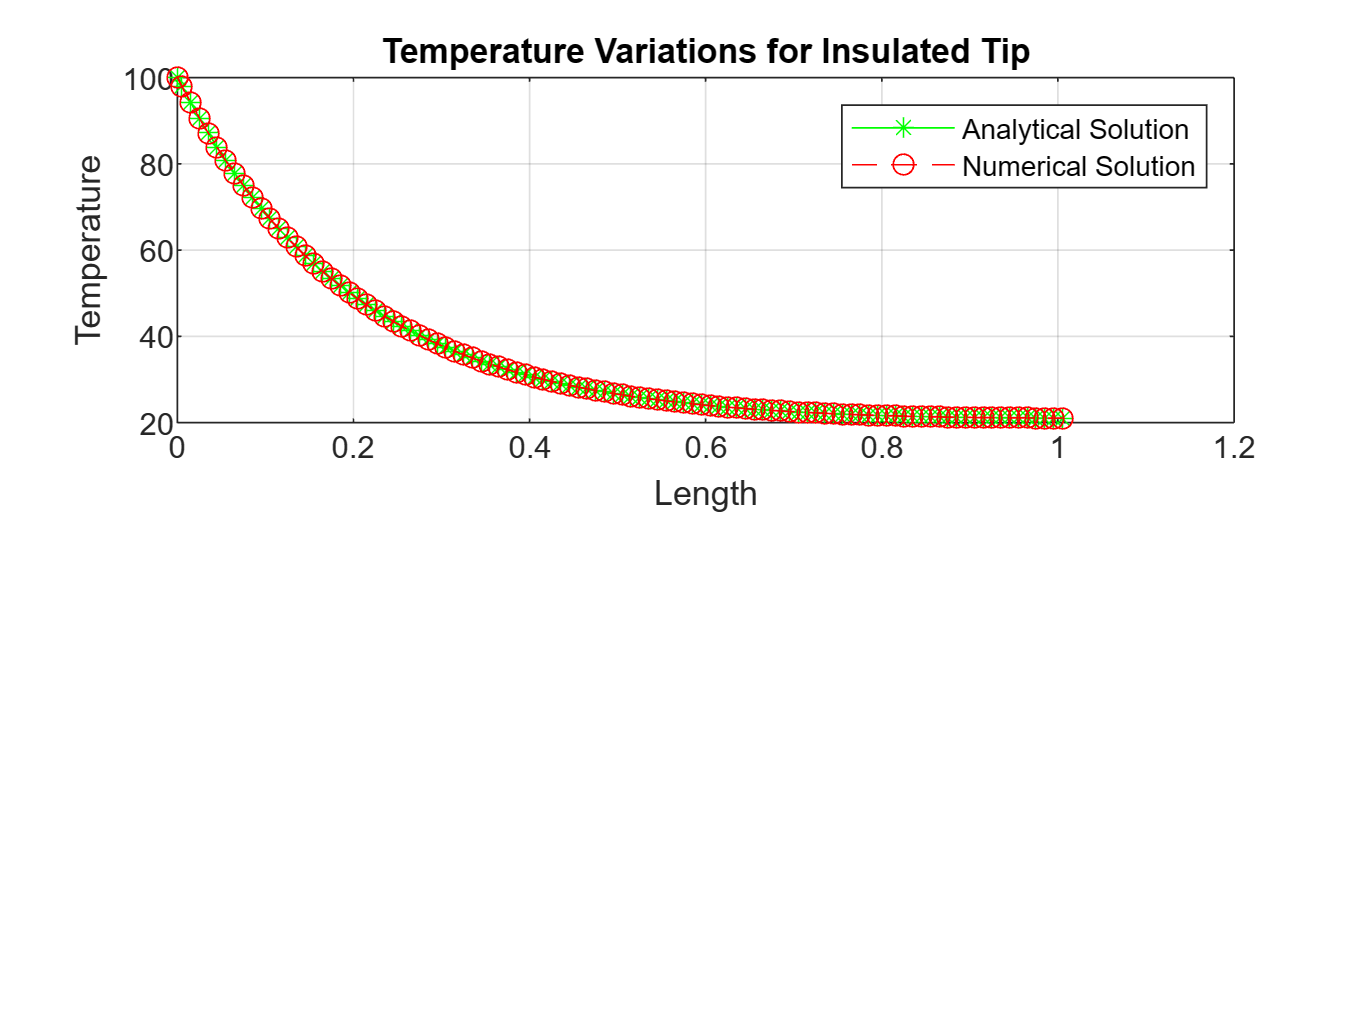

figure;
tiledlayout(2,1)
nexttile
%for analytical graph
plot(array_temps_analytical(:,2),array_temps_analytical(:,1), 'g*-');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations for Insulated Tip');
grid on
hold on

%for numerical solution graph
plot(array_temps(:,2),array_temps(:,1), 'ro--');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations for Insulated Tip');

legend('Analytical Solution', 'Numerical Solution')
grid on
hold off

### For an infinitely long fin (End at ambient Temperature):

ANALYTICAL SOLUTION FOR END AT T_amb:

array_temps_analytical = zeros(N_points+2, 2);
dx = zeros(N_points + 2, 1);
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);
x(1) = 0;

for i = 2:1:N_points+2 % Generating x points from delta
    x(i) = x(i-1) + dx(i-1);
end

for i = N_points+2:-1:1
    array_temps_analytical(i,1) = T_amb + (Ti - T_amb)*((cosh(m*(L-x(i)))+sinh(m*(L-x(i))))/(cosh(m*L)+sinh(m*L)));
    array_temps_analytical(i,2) = x(i);
end

NUMERICAL SOLUTION FOR END AT T_amb:

% Initializing important parameters for the given problem
x = zeros(N_points+2, 1); % For the unit lengths
a = zeros(N_points+2, 1); % For the right side of the matrix diagonal elements
b = zeros(N_points+2, 1); % For the left side of the matrix diagonal elements
d = zeros(N_points+2, 1); % For the diagonal Elements of the matrix
c = zeros(N_points+2, 1); % For the equation's answers

array_temps = zeros(N_points+2, 2); % For the equation's answers

dx = zeros(N_points + 2, 1);
for i = 2:1:N_points+1
dx(i) = L/N_points;
end
dx(1) = L/(N_points * 2);
dx(N_points+2) = L/(N_points * 2);
% disp(dx)

x(1) = 0;
for i = 2:1:N_points+2 % Getting all the points from the delta
x(i) = x(i-1) + dx(i-1);
end

% Initial Boundary Conditions
a(1) = 0;
b(1) = 0;
c(1) = Ti;
d(1) = 1;
m2 = 25;

% Thermal Conductivity for the remaining points except for the last one
for i = 2:1:N_points+1
    d(i) = -(1/(dx(i-1)) + 1/dx(i+1) + m2*(L/N_points)); % ST
    a(i) = (1/dx(i+1));
    b(i) = (1/dx(i-1));
    c(i) = (-m2*T_amb)*(L/N_points); % SC
end

% Final Boundary Conditions
a(N_points + 2) = 0;
b(N_points + 2) = 0;
d(N_points + 2) = 1;
c(N_points + 2) = T_amb;

for i = 2:1:N_points+2
    d(i) = d(i) - b(i)*a(i-1)/d(i-1);
    c(i) = c(i) - b(i)*c(i-1)/d(i-1);
end

for i = 1:1:N_points+2
    disp(d(i));
end

     1

 -300.2500

 -166.9444

 -140.3498

 -128.9995

 -122.7303

 -118.7705

 -116.0540

 -114.0832

 -112.5947

 -111.4359

 -110.5123

 -109.7623

 -109.1441

 -108.6280

 -108.1927

 -107.8223

 -107.5048

 -107.2309

 -106.9933

 -106.7862

 -106.6049

 -106.4457

 -106.3054

 -106.1814

 -106.0716

 -105.9740

 -105.8872

 -105.8099

 -105.7409

 -105.6792

 -105.6240

 -105.5746

 -105.5302

 -105.4904

 -105.4547

 -105.4225

 -105.3936

 -105.3676

 -105.3441

 -105.3230

 -105.3040

 -105.2869

 -105.2714

 -105.2574

 -105.2448

 -105.2334

 -105.2232

 -105.2139

 -105.2055

 -105.1980

 -105.1911

 -105.1849

 -105.1794

 -105.1743

 -105.1697

 -105.1656

 -105.1619

 -105.1585

 -105.1555

 -105.1527

 -105.1502

 -105.1480

 -105.1459

 -105.1441

 -105.1424

 -105.1409

 -105.1395

 -105.1383

 -105.1372

 -105.1362

 -105.1353

 -105.1344

 -105.1337

 -105.1330

 -105.1324

 -105.1318

 -105.1313

 -105.1309

 -105.1305

 -105.1301

 -105.1298

 -105.1295

 -105.12


% Final equations for back propogation
array_temps(N_points+2,1) = c(N_points+2)/d(N_points+2);
array_temps(N_points+2,2) = x(N_points+2);

for i = N_points+1:-1:1
    array_temps(i,1) = (c(i) - a(i)*array_temps(i+1,1))/d(i);
    array_temps(i,2) = x(i);
end


Plotting a graph for Tip at Ambient temperature:

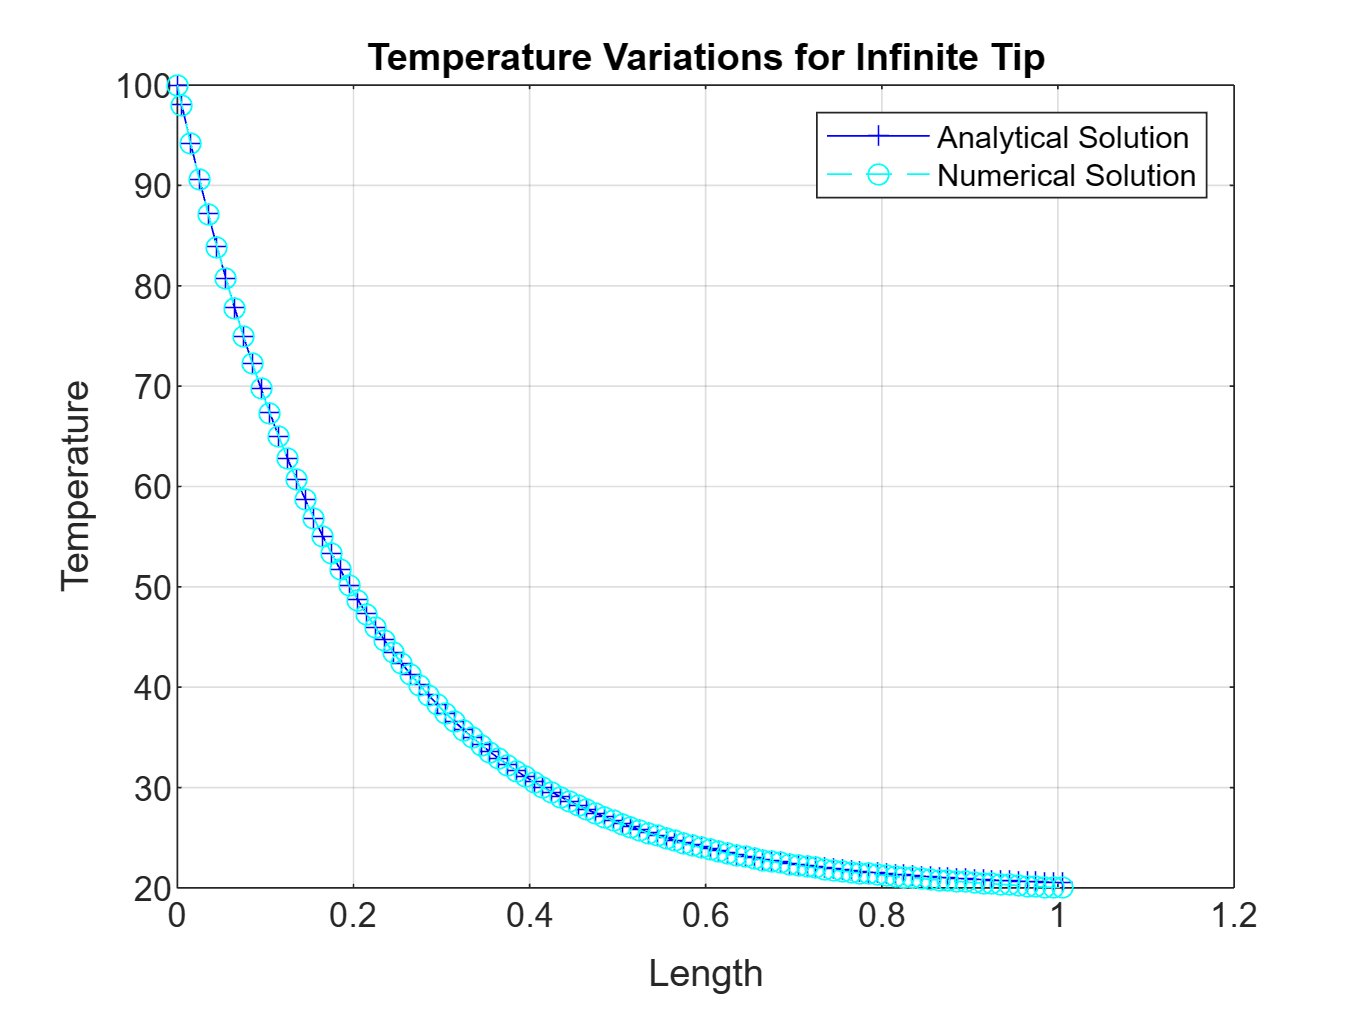

figure;
nexttile
%for analytical graph
plot(array_temps_analytical(:,2),array_temps_analytical(:,1), 'b+-');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations for Infinite Tip');
grid on
hold on

%for numerical solution graph
plot(array_temps(:,2),array_temps(:,1), 'co--');
xlabel('Length');
ylabel('Temperature');
title('Temperature Variations for Infinite Tip');

legend('Analytical Solution', 'Numerical Solution')
grid on
hold off